# Lecture 11: Image Compression

# Huffman Coding Examples

Author: Dr. Zeynep Cipiloglu Yildiz

Notes:

- Sample images are available in the images folder of the current directory. (You may need to add images folder into your path.)

- Related lecture: Lecture11 - Image Compression

- pdf versions of the .mlx files are also available for those using GNU Octave

- huffmandict, huffmanenco, huffmandeco functions are part of Communications System Toolbox

% clear workspace variables and close windows
clc, clearvars, close all;

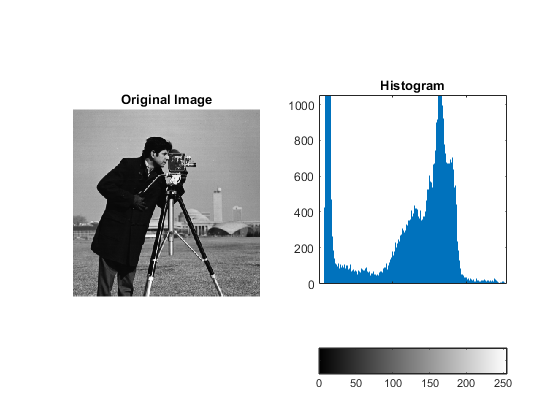

% read image
I = imread('images/cameraman.tif');

% display the image and its histogram
figure, subplot(1,2,1), imshow(I), title('Original Image')
subplot(1,2,2), imhist(I), axis('square'), title('Histogram') % observe the uniformity level of the histogram

**1. Generate Huffman dictionary**

% calculate normalized image histogram as probability values
h = imhist(I);
h = h/numel(I); % normalize the histogram by dividing its elements to total num of pixels
sum(h) % the sum of the values of a normalized histogram must always be 1

ans = 1

intensities = (0:255); % intensity values to be coded
[dict, Lavg] = huffmandict(intensities, h); % generate Huffman dictionary

**2. Encoding and decoding the image according to the dictionary**

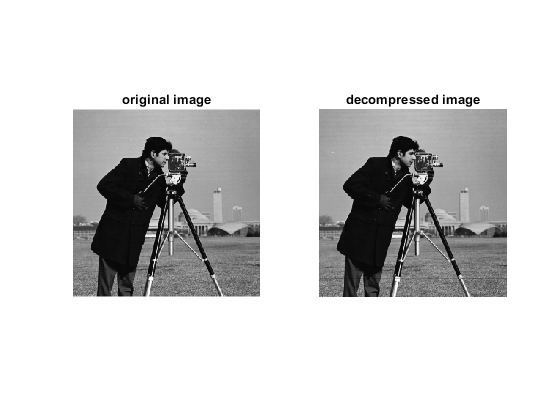

% encode image
comp = huffmanenco(I(:),dict);

% decode image
decomp = huffmandeco(comp, dict);

% reshape decompressed vector to original size
Idec = reshape(decomp, size(I));
Idec = uint8(Idec);

% display the original and decompressed images
figure, subplot(1,2,1), imshow(I), title('original image');
subplot(1,2,2), imshow(Idec), title('decompressed image');

**Performance measures**

% check the difference between the original and decompressed images
dif = I-Idec;
sum(dif(:))

ans = 0

Image entropy:

Ientropy = entropy(I)

Ientropy = 7.0097

Compare entropy and Lavg. Is it lossless or lossy compression?

Lavg

Lavg = 7.0448

Compression ratio:

C = 8/Lavg

C = 1.1356

Relative data redundancy:

R = 1 - 1/C

R = 0.1194